# Create Constant-Velocity Linear Kalman Filter

Create a linear Kalman filter that uses a 2D constant velocity motion model. Assume that the measurement consists of the  *xy-*location of the object.

Specify the initial state estimate to have zero velocity.

x = 5.3;
y = 3.6;
initialState = [x;0;y;0];
KF = trackingKF('MotionModel','2D Constant Velocity','State',initialState);

Create measured positions for the object on a constant-velocity trajectory.

vx = 0.2;
vy = 0.1;
T  = 0.5;
pos = [0:vx*T:2;
       5:vy*T:6]';

Predict and correct the state of the object.

for k = 1:size(pos,1)
    pstates(k,:) = predict(KF,T);
    cstates(k,:) = correct(KF,pos(k,:));
end

Plot the tracks.

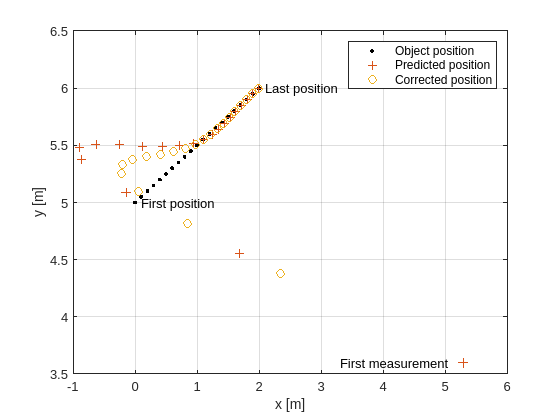

plot(pos(:,1),pos(:,2),"k.",pstates(:,1),pstates(:,3),"+", ...
    cstates(:,1),cstates(:,3),"o")
xlabel("x [m]")
ylabel("y [m]")
grid
xt  = [x-2, pos(1,1)+0.1, pos(end,1)+0.1];
yt = [y, pos(1,2), pos(end,2)];
text(xt,yt,["First measurement","First position","Last position"])
legend("Object position","Predicted position","Corrected position")

*Copyright 2012 The MathWorks, Inc.*